# EE115 Lab 3

# Buddy Ugwumba

1) Plot and discuss $m\left\lbrack n\right\rbrack$, $u\left\lbrack n\right\rbrack$,. and $v\left\lbrack n\right\rbrack$ for $n=0,1,\ldotp \ldotp \ldotp 63$. What is the time scale for each incrememnt of $n$. 

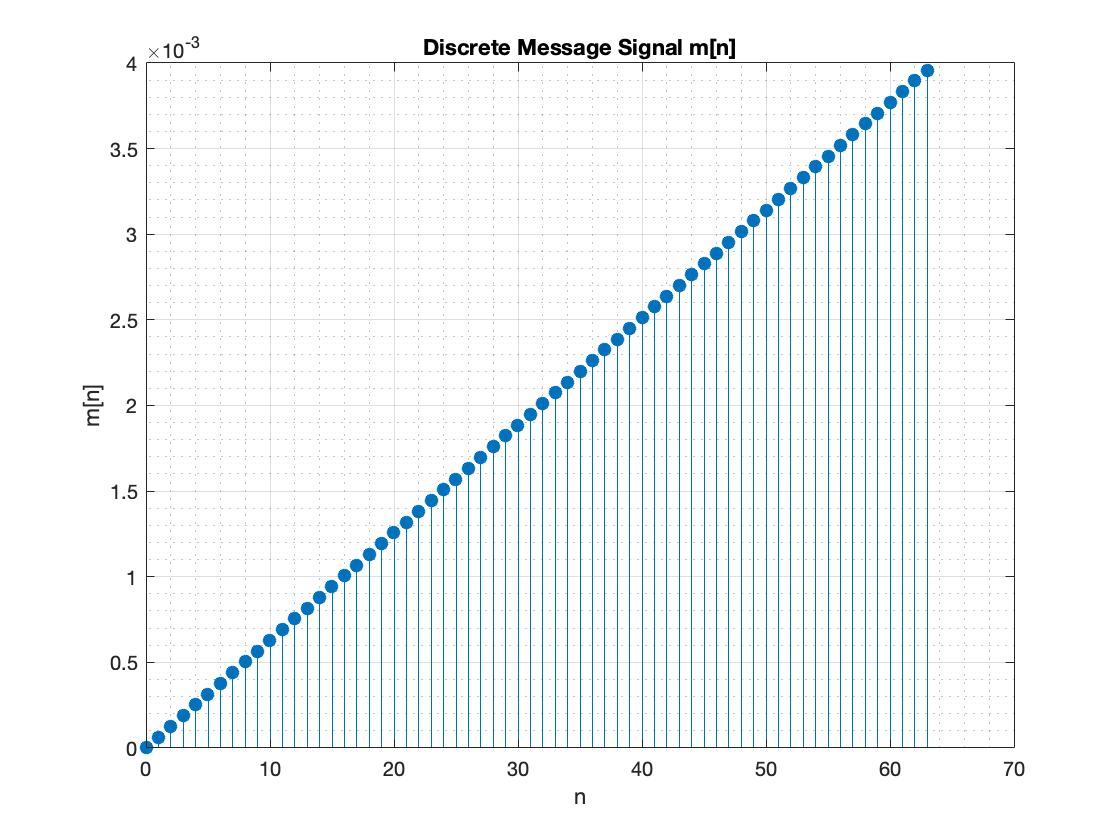

clear all
n = 0:1:63;
m = sin(pi*n*0.00002);
m(n>63) = 0;
m(n<0) = 0;
figure
stem(n, m, 'filled');
xlabel('n');
ylabel('m[n]');
title('Discrete Message Signal m[n]')
grid on
grid minor

The timescale for this increment of n is

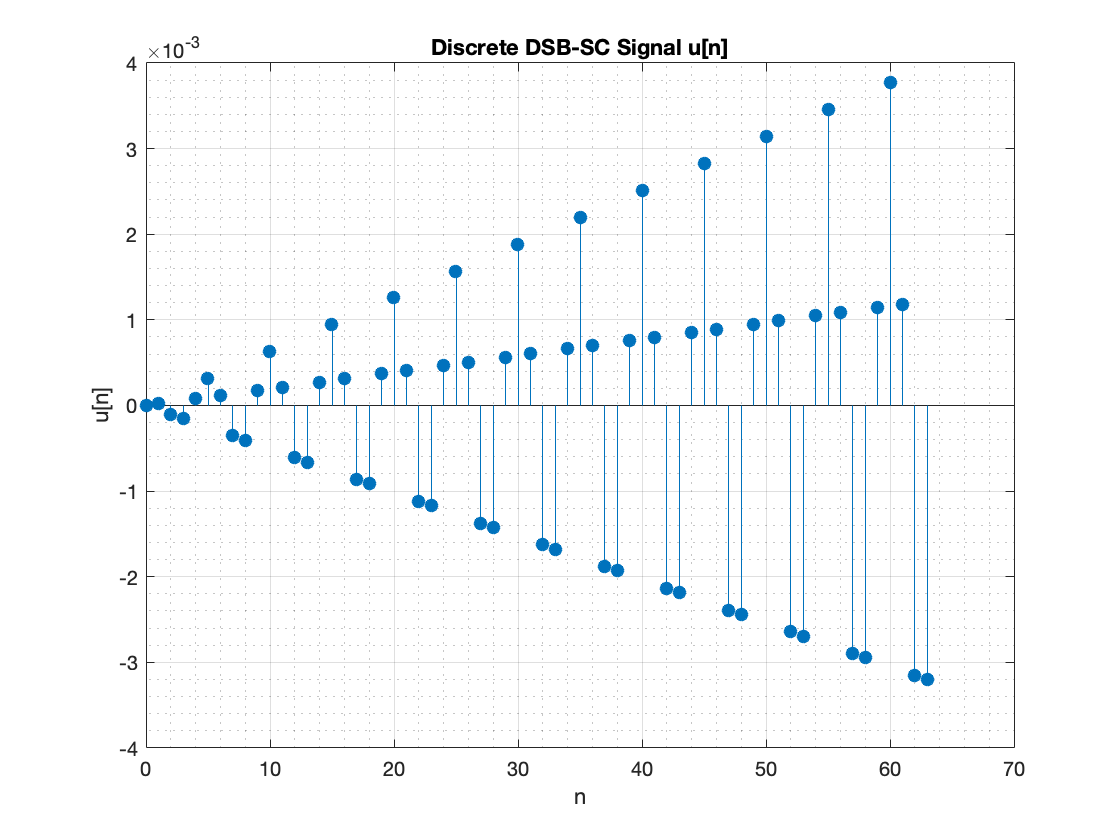

u = m.*cos(2*pi*n*(1/5));
figure
stem(n, u, 'filled')
xlabel('n')
ylabel('u[n]')
title('Discrete DSB-SC Signal u[n]')
grid on
grid minor

The timescale of this increment of n is 

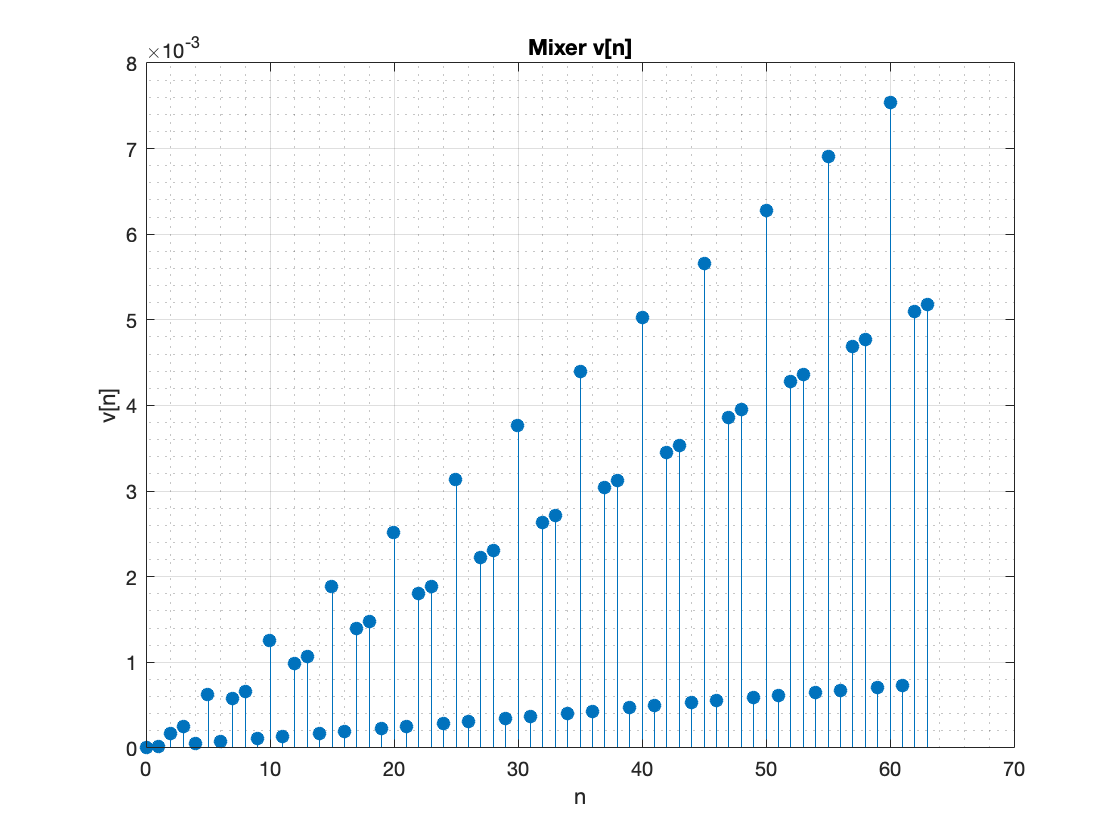

v = 2*u.*cos(2*pi*n*1/5);
figure
stem(n, v, 'filled')
xlabel('n')
ylabel('v[n]')
title('Mixer v[n]')
grid on
grid minor

The timescale or period for each increment of n is 0.0002s. 

2) Compute and plot the amplitude spectra $|M\left\lbrack k\right\rbrack |$, $|U\left\lbrack k\right\rbrack |$, and $|V\left\lbrack k\right\rbrack |$ for $-32\le k\le 32$ and dsicuss their bandwidths

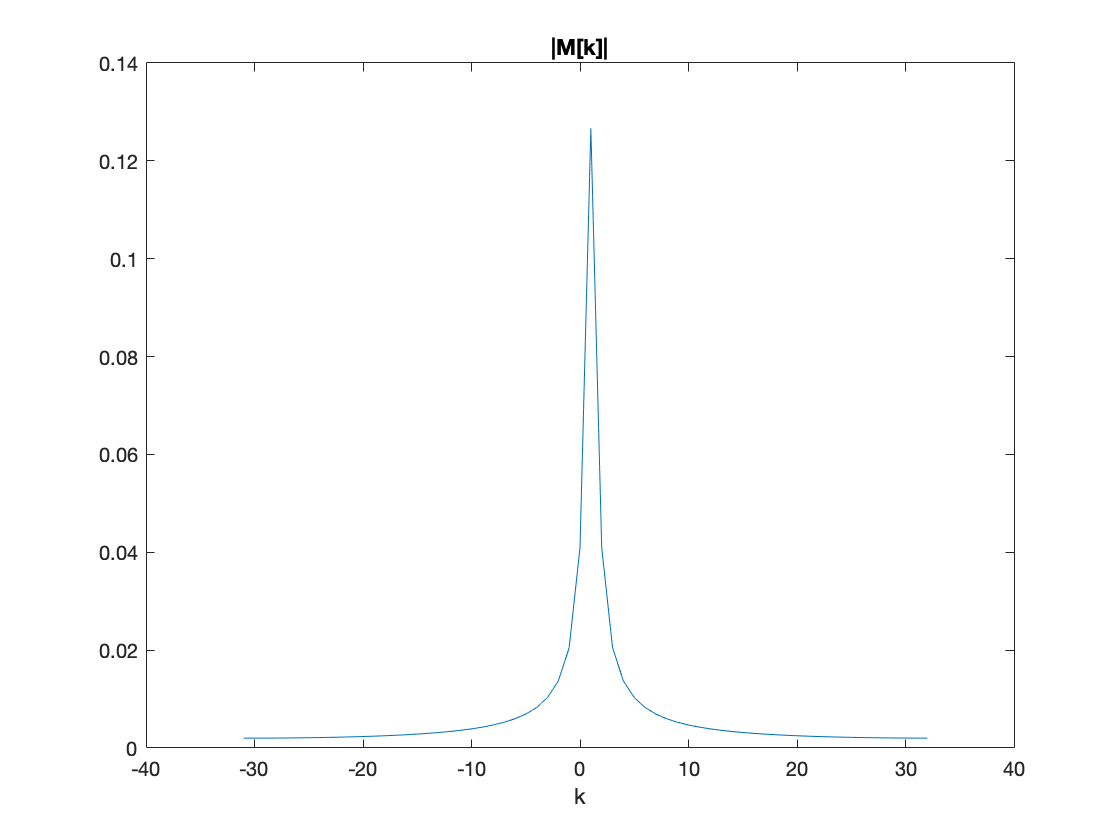

k = -31:1:32;
f_s = 50000;
T_s = 1/f_s;
t = 0:T_s:63*T_s;
m_t = sin(pi*t);
M_K = fftshift(fft(m_t));
M = abs(M_K);
figure
plot(k, M)
title('|M[k]|');
xlabel('k')

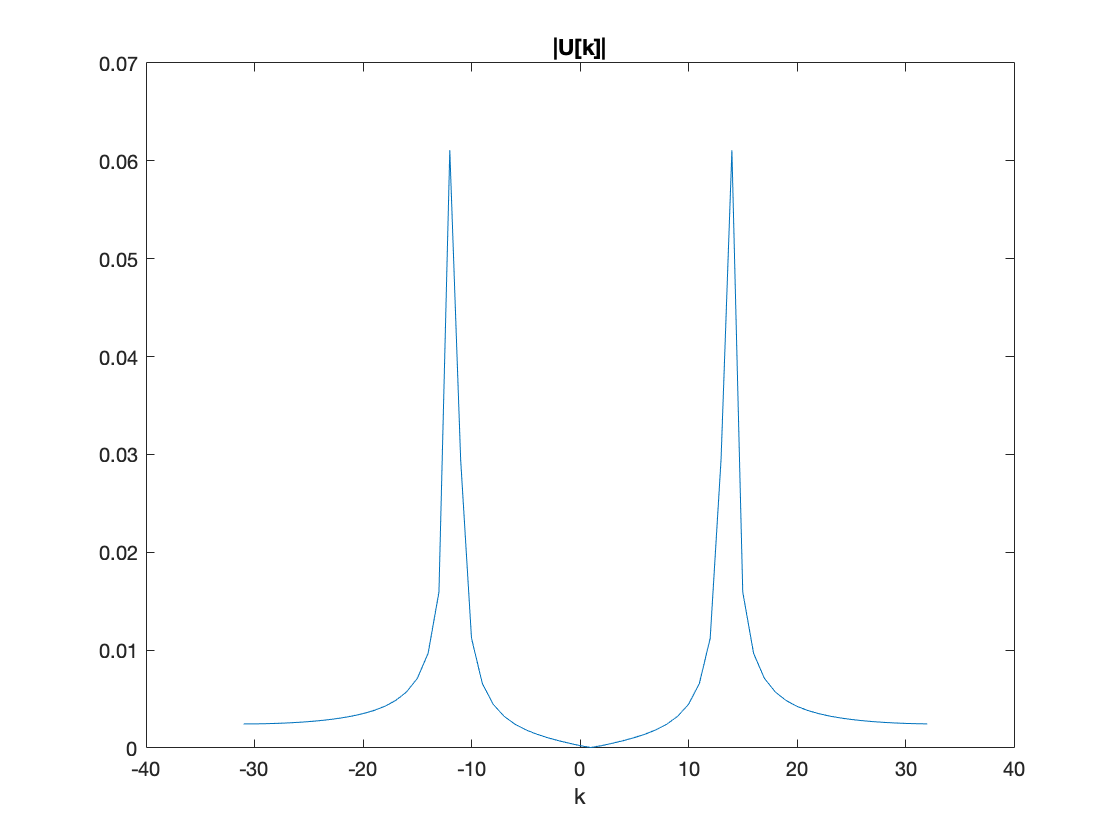

u_t = m_t.*cos(2*pi*(1/5)*k);
U_K = fftshift(fft(u_t));
U = abs(U_K);
figure
plot(k, U)
title('|U[k]|');
xlabel('k')

Multiplicatioon in the time—domain is convolution in the frequency domain. Therefore, the AM signal $u\left(t\right)$ experiences a shift in both the negative and positive frequency components because of the convolution with the carrier signal. 

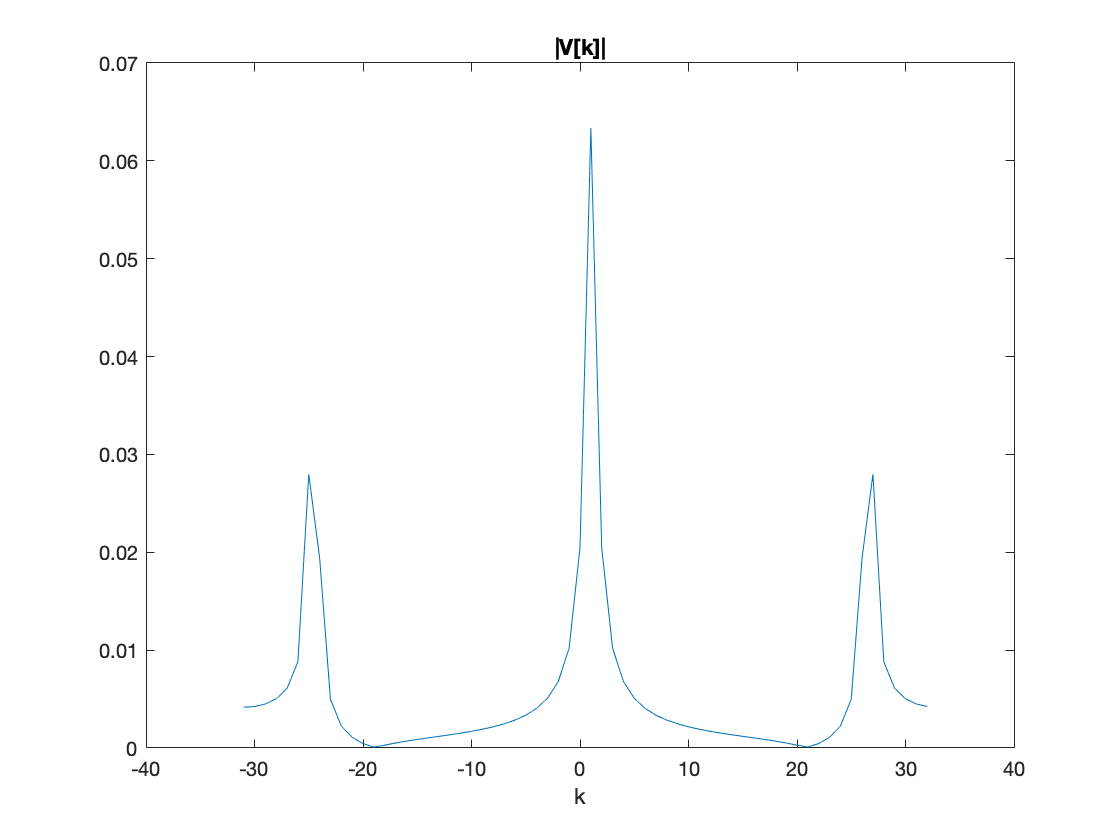

v_t = u_t.*cos(2*pi*(1/5)*k);
V_K = fftshift(fft(v_t));
V = abs(V_K);
figure
plot(k, V)
title('|V[k]|');
xlabel('k')

According to theory, taking the fourier transfrom of a sinusoidal signal should produce two delta spikes—one at the negative and positive axis of the frequency. Specific to this function, we should spikes at $\pm 0\ldotp 5\ldotp$However, here we see only one spike. This is because the resolution is too high due to the frequency sampling value. When we reduce the frequency sampling value, so that when the frequency is multiplied by the integer value of k, we get the expected spectral image.

3. Since we wish to find the value for W, toi recover the inital message signal, we can use the fact that a relationship exists between the value of n given in the first question: $n_1 =0,1,\ldotp \ldotp \ldotp 63$, and the value of n given in this question $n_2 =0,1,\ldotp \ldotp \ldotp L$ if we assume that the two are equal, since we want to recover the original message signal we can set L = 63. Now, using the equatioon given for L being $L=\frac{8}{T_s *W}$ we can solve for W by manipulating the given equation: $W=\frac{8}{T_s *L}$ this gives us approximately 6349.21. In problem 4 I found that 6349 to the limit that W could be. Before I found this out I made a guess using the value for $f_s$. I realized that the value was too high because n was much larger than the original value of 63 and decreased by an order of magnitude. Fumbling around I landed at 6300. I still do not fully understand the relationship between the the window of a low-pass filter and the frequency of a normalized message.  

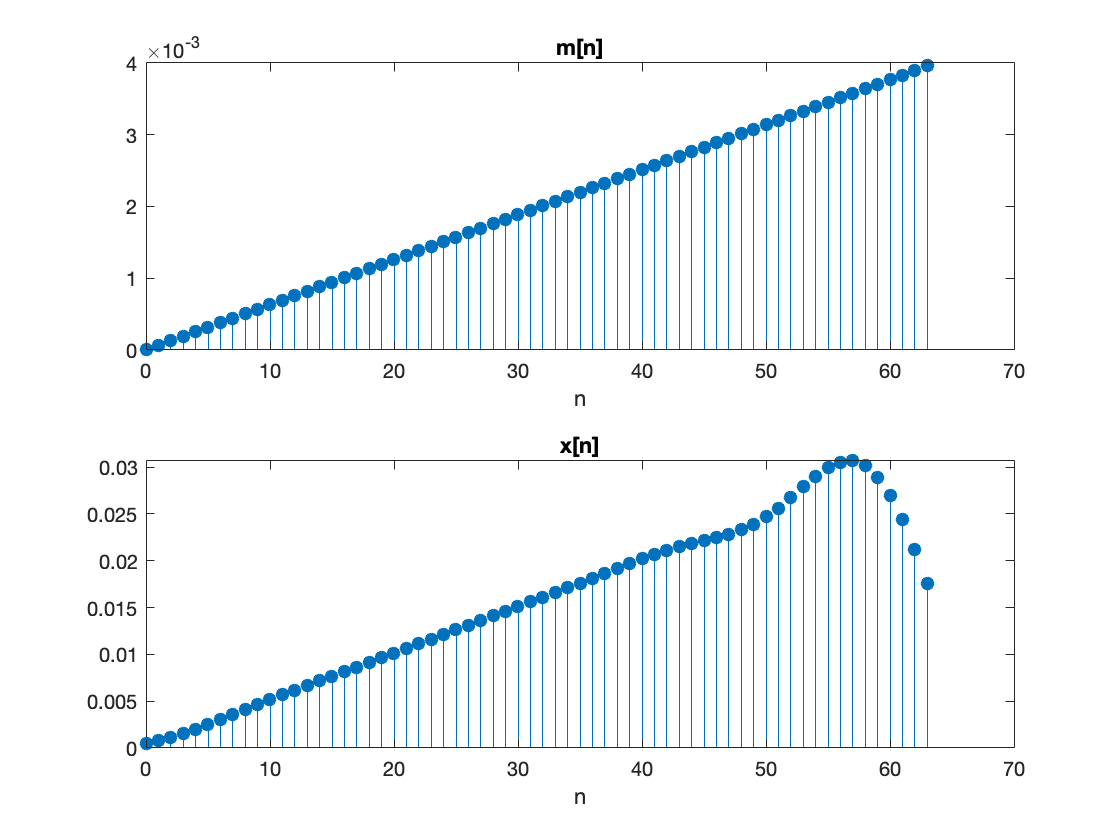

W = 6300;
L = 8/(T_s*W);
n = 0:1:L;
h = W*sinc(W*n*T_s -4).*(0.5+0.5*cos(pi*(W/4*(n*T_s -4/W))));
h_n = (1/W)*h;
x_n = conv(h_n,v,'same');
subplot(2,1,1);
stem(n,m,'filled');
title('m[n]')
xlabel('n')
subplot(2,1,2);
stem(n,x_n,'filled');
title('x[n]')
xlabel('n')

In theory, when working with a a low-pass filter, we always assume that we can make a perfect rectangular low-pass filter. However, in practice that is not possible. We see that here when we try to recover the original message signal. Towards the end there is less similarity between the convolved signal and the original message signal. 

4

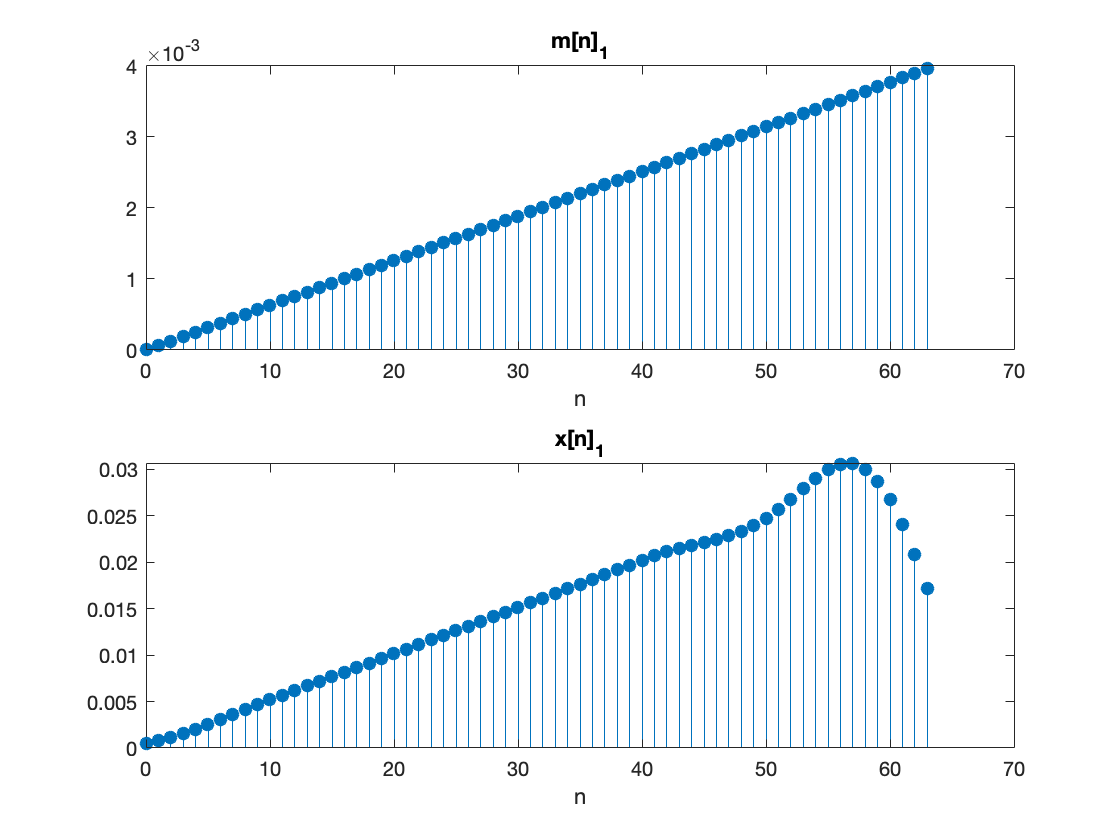

W = 6319;
L = 8/(T_s*W);
n = 0:1:L;
h = W*sinc(W*n*T_s -4).*(0.5+0.5*cos(pi*(W/4*(n*T_s -4/W))));
h_n = (1/W)*h;
x_n = conv(h_n,v,'same');
subplot(2,1,1);
stem(n,m,'filled');
title('m[n]_1')
xlabel('n')
subplot(2,1,2);
stem(n,x_n,'filled');
title('x[n]_1')
xlabel('n')

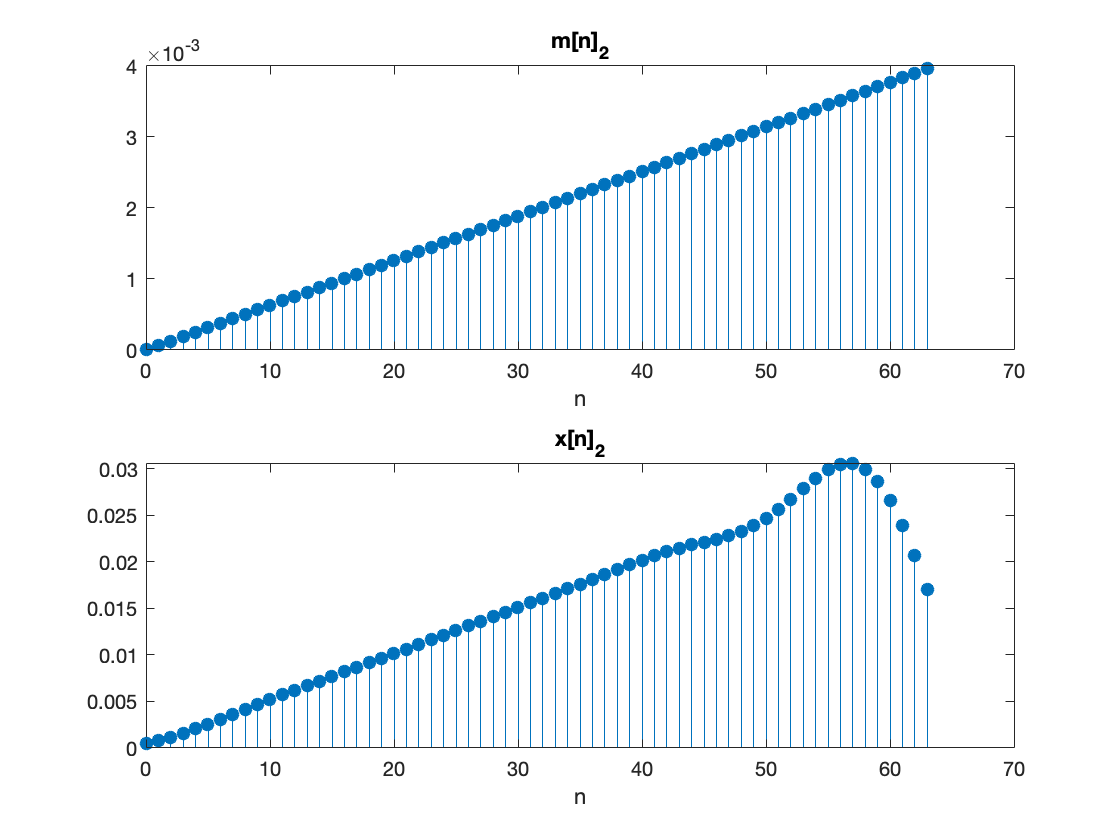

W = 6325;
L = 8/(T_s*W);
n = 0:1:L;
h = W*sinc(W*n*T_s -4).*(0.5+0.5*cos(pi*(W/4*(n*T_s -4/W))));
h_n = (1/W)*h;
x_n = conv(h_n,v,'same');
subplot(2,1,1);
stem(n,m,'filled');
title('m[n]_2')
xlabel('n')
subplot(2,1,2);
stem(n,x_n,'filled');
title('x[n]_2')
xlabel('n')

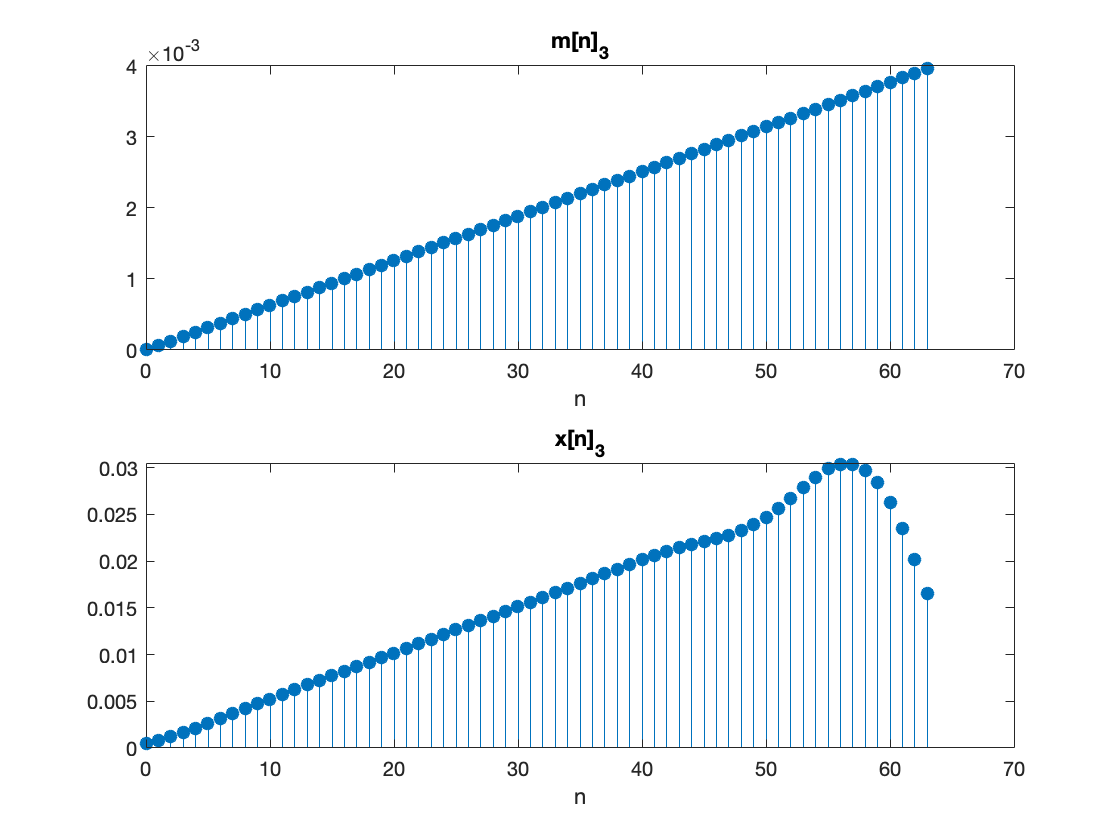

W = 6349;
L = 8/(T_s*W);
n = 0:1:L;
h = W*sinc(W*n*T_s -4).*(0.5+0.5*cos(pi*(W/4*(n*T_s -4/W))));
h_n = (1/W)*h;
x_n = conv(h_n,v,'same');
subplot(2,1,1);
stem(n,m,'filled');
title('m[n]_3')
xlabel('n')
subplot(2,1,2);
stem(n,x_n,'filled');
title('x[n]_3')
xlabel('n')

It appears that any value of W between 6300 and 6349 will suffice.